
hunThou = 1000 * 100;
data = rand(hunThou,1000);

projectDims = [2,5,10,25,50,100,200,350,500];

creationTimes = zeros(5,size(projectDims,2));
projectionTimes = zeros(7,size(projectDims,2));



iterations = 10000;

for dimIndex = 1 : size(projectDims,2)
    projectTo = projectDims(dimIndex);

    tic;
    rproj = RandomProjection(1000,projectTo);
    creationTimes(1,dimIndex) = toc;

    tic;
    pproj = PcaProjection(data(1:1000,:),projectTo);
    creationTimes(2,dimIndex) = toc;

    tic;
    nproj = NsimpProjection(data(1:1000,:),projectTo,@euc);
    creationTimes(3,dimIndex) = toc;

    tic;
    mproj = MdsProjection(data(1:1000,:),projectTo);
    creationTimes(4,dimIndex) = toc;

    tic;
    lproj = LmdsProjection(data(1:1000,:),projectTo,@euc);
    creationTimes(5,dimIndex) = toc;


    
    tic;
    test = rproj.project(data(1:iterations,:));
    projectionTimes(1,dimIndex) = toc / iterations;

    tic;
    test = pproj.project(data(1:iterations,:));
    projectionTimes(2,dimIndex) = toc / iterations;


    tic;
    for i = 1 : iterations
        test = rproj.project(data(i,:));
    end
    projectionTimes(3,dimIndex) = toc / iterations;

    tic;
    for i = 1 : iterations
        test = nproj.project(data(i,:));
    end
    projectionTimes(4,dimIndex) = toc / iterations;

    tic;
    for i = 1 : iterations
        test = mproj.project(data(i,:));
    end
    projectionTimes(5,dimIndex) = toc / iterations;

    tic;
    for i = 1 : iterations
        test = lproj.project(data(i,:));
    end
    projectionTimes(6,dimIndex) = toc / iterations;
end



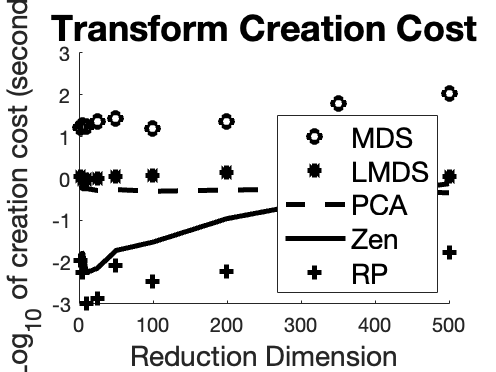


figure;
hold on;

title("Transform Creation Cost","FontSize",18);
xlabel("Reduction Dimension","FontSize",14);
ylabel("Log_{10} of creation cost (seconds)","FontSize",14);

% almost unbelievable, live scripts don't support loglog or semilog plots!!
plot(projectDims,log(creationTimes(4,:)) / log(10),"ok","LineWidth",2.5);
plot(projectDims,log(creationTimes(5,:)) / log(10),"*k","LineWidth",2.5);
plot(projectDims,log(creationTimes(2,:)) / log(10),"--k","LineWidth",2.5);
plot(projectDims,log(creationTimes(3,:)) / log(10),"-k","LineWidth",2.5);
plot(projectDims,log(creationTimes(1,:)) / log(10),"+k","LineWidth",2.5);

legend("MDS","LMDS","PCA","Zen","RP","FontSize",14,"Location","southeast")
hold off;

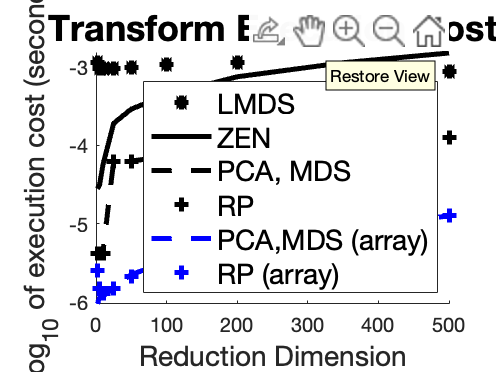


figure;
hold on;

title("Transform Execution Cost","FontSize",18);
xlabel("Reduction Dimension","FontSize",14);
ylabel("Log_{10} of execution cost (seconds)","FontSize",14);

% almost unbelievable, live scripts don't support loglog or semilog plots!!
plot(projectDims,log(projectionTimes(6,:)) / log(10),"*k","LineWidth",2.5);
plot(projectDims,log(projectionTimes(4,:)) / log(10),"-k","LineWidth",2.5);
plot(projectDims,log(projectionTimes(5,:)) / log(10),"--k","LineWidth",2.5);
plot(projectDims,log(projectionTimes(3,:)) / log(10),"+k","LineWidth",2.5);
plot(projectDims,log(projectionTimes(2,:)) / log(10),"--b","LineWidth",2.5);
plot(projectDims,log(projectionTimes(1,:)) / log(10),"+b","LineWidth",2.5);

legend("LMDS","ZEN","PCA, MDS","RP","PCA,MDS (array)","RP (array)","FontSize",14,"Location","southeast");
hold off;